(22.76 + 23.43)/2
deg2rad((22.76 + 23.43)/2)

global a b lambda_theo b_SingleSlit
a = 8.5;
b = 3.5;
b_SingleSlit = 8;
lambda_theo = 3.1892;
k_theo = 2*pi/lambda_theo;

lambda = b_SingleSlit*sind(23.095)
eta = abs((lambda_theo - lambda))/lambda_theo*100

I_theo = @(theta) 190 * sin(0.5*k_theo*b_SingleSlit*sin(theta)) ./ (0.5*k_theo*b_SingleSlit*sin(theta));
theta_deg_array = [linspace(-50, -0.001, 100), linspace(0.001, 50)];
%theta_array = deg2rad(theta_deg_array);
MyPlot(theta_deg_array, I_theo(deg2rad(theta_deg_array)));


## 1.1 单缝衍射


Export = 0;
U_positive = [
189.2	175	163.8	157.5	147.9	131.6	112.3	93.7	77.5	57.4	42.5	28.1	10.8	1.1	0.1	0	0.1	0.2	0.3	1.3	2.2	2	0.5	0.2	1.0	1.3	0.8
];
U_negtive = [
189.2	170	120.6	107.6	108.5	112.9	112.0	107.4	94.1	48.3	24.9	10.3	3.0	0.2	0.0	0.0	0.0	0.1	0.9	2.9	2.3	0.3	0.0	1.7	4.7	1.7	0.3
];
U_negtive = U_negtive(end:-1:1); % 转换为 -50 deg 开始
I = [U_negtive, U_positive];

I_range = [0 200];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = [
0	2	4	5	6	7	8	9	10	12	14	16	18	20	22	24	26	28	30	32	34	36	38	40	42	44	45    
];
theta_deg_array = [-theta_deg_array(end:-1:1), theta_deg_array];
theta_deg_array = theta_deg_array/2 + 25;

stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';


% 补测的几个数据点：
MyScatter_ax(stc.axes, [45	5	7	9]/2+25, [0.8	157.5	131.6	93.7]);

sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Single-Slit";



if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 1.2 单缝 极小 +

% 作图
clc, clear, close all
Export = 0;

I = [
13.8	2.4	0.7	0.0	0.2	1.4	8.8	19.0	29.2
];
I_max = 30;
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Single-Slit (Min, Positive)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 1.3 单缝 极小 -

% 作图
clc, clear, close all
Export = 0;

I = [
13.8	2.4	0.7	0.0	0.2	1.4	8.8	19.0	29.2
];
I_max = 30;
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Single-Slit (Min, Positive)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 2. 双缝干涉/衍射

U_negtive = [
142.8	126.8	97.5	38.2	1.5	0.4	3.3	17.4	46.3	81.5	99	93.6	60.4	32.5	8.9	4.7	5.1	9.5	16.2	14.1	5	3.1	16.1	40.3	25.9	3.4
];
U_negtive = U_negtive(end:-1:1) % 转换为 -50 deg 开始
U_positive = [
142.8	138.4	116.3	64.6	12.3	0.6	0.2	5.7	29.2	54.5	81.6	100.2	98	71.3	28	7.5	3.4	3.6	5.5	11.8	11.6	4.8	3.6	16.4	35.3	28.4    
];
I = [U_negtive, U_positive];
theta_deg_array = [-50:2:0, 0:2:50];
theta_rad_array = deg2rad(theta_deg_array);


%MyScatter(theta_deg_array, I)
%MyPlot(theta_deg_array, I)


299792458/9.4e9*100
vpa(299792458/9.4e9*100)

global a b lambda 
lambda = 3.1915e-2

lambda = 0.0319

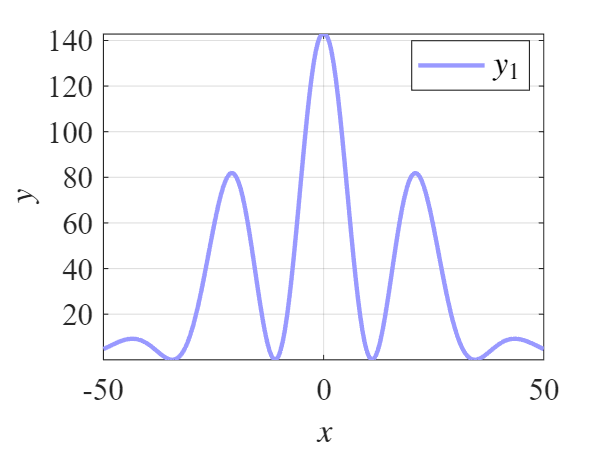

a = 8.5e-2;
b = 3.5e-2;
sinc = @(x) sin(x)./x;
alpha = @(theta) pi*a/lambda*sin(theta);
beta = @(theta) pi*b/lambda*sin(theta);
I_theo = @(theta) 142.8*sinc(beta(theta)).^2 .* cos(alpha(theta)).^2;

theta_deg_array = [linspace(-50, -0.001, 100), linspace(0.001, 50, 100)];
stc = MyPlot(linspace(-50, 50, 200), I_theo(deg2rad(theta_deg_array)));

sca = MyScatter_ax(stc.axes, [-50:2:0, 0:2:50], I);

函数或变量 'I' 无法识别。

MyColors = GetMyColors;
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

% 测试用
global a b lambda 
lambda = 3.696e-2
a = 8.5e-2;
b = 3.5e-2;
sinc = @(x) sin(x)./x;
alpha = @(theta) pi*a/lambda*sin(theta);
beta = @(theta) pi*b/lambda*sin(theta);
I_theo = @(theta) 142.8*sinc(beta(theta)).^2 .* cos(alpha(theta)).^2;

theta_deg_array = [linspace(-50, -0.001, 100), linspace(0.001, 50, 100)];
stc = MyPlot(linspace(-50, 50, 200), I_theo(deg2rad(theta_deg_array)));
sca = MyScatter_ax(stc.axes, [-50:2:0, 0:2:50], I);
MyColors = GetMyColors;
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
MyPlot_ax(stc.axes, [-50:2:0, 0:2:50], I_theo(deg2rad([(-50:2:0) - 0.001, 0.001 + (0:2:50)])))

close all
% 搜索 lambda 
Struct_SA.Var.num = 1; % 一个参数
Struct_SA.Var.range = [3.1e-2 4e-2 3.2e-2];
Struct_SA.Annealing.T_0 = 100;        % 初始温度
Struct_SA.Annealing.alpha = 0.97;        % 降温系数
Struct_SA.Annealing.T_end = 0.01;         % 停止温度
Struct_SA.Annealing.mkvlength = 6;   % 马尔科夫链长度

Struct_SA = MySimulatedAnnealing(Struct_SA, @(x) func_1_1_GetError(x, I));
vpa(Struct_SA.X_best)

func_1_1_GetError(0.028, I)


%stc.TickLength = [0.02 0.06];

% Refer to https://github.com/YiDingg/Matlab to get this function
%MyExport_pdf  
global a b lambda 
lambda = 3.1915e-2
a = 8.5e-2;
b = 3.5e-2;
sinc = @(x) sin(x)./x;
alpha = @(theta) pi*a/lambda*sin(theta);
beta = @(theta) pi*b/lambda*sin(theta);
I_theo = @(theta) 50*sinc(beta(theta)).^2 .* cos(alpha(theta)).^2;

## 2.1 双缝干涉

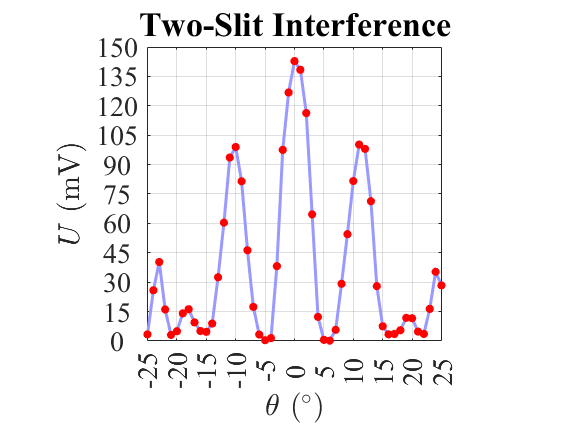

clc, clear, close all
U_negtive = [
142.8	126.8	97.5	38.2	1.5	0.4	3.3	17.4	46.3	81.5	99	93.6	60.4	32.5	8.9	4.7	5.1	9.5	16.2	14.1	5	3.1	16.1	40.3	25.9	3.4
];
U_negtive = U_negtive(end:-1:1); % 转换为 -50 deg 开始
U_positive = [
142.8	138.4	116.3	64.6	12.3	0.6	0.2	5.7	29.2	54.5	81.6	100.2	98	71.3	28	7.5	3.4	3.6	5.5	11.8	11.6	4.8	3.6	16.4	35.3	28.4    
];
theta_deg_array = [-50:2:0, 0:2:50];
theta_rad_array = deg2rad(theta_deg_array);
I = [U_negtive, U_positive];

Export = 0;

theta_deg_array = [linspace(-50, -0.001, 100), linspace(0.001, 50, 100)];
stc = MyPlot([0:1:25, 25:1:50], I/150*50);
sca = MyScatter_ax(stc.axes, [0:1:25, 25:1:50], I/150*50);
MyColors = GetMyColors;
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit Interference";
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.axes.XTick = 0:5:50;
stc.axes.XTickLabel = stc.axes.XTick  - 25;

ylim([0 50])
stc.axes.YTick = 0:5:50;
stc.axes.YTickLabel = stc.axes.YTick/50*150;


if Export == 1
    MyExport_pdf
end
%MyExport_pdf


xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end


## 2.2 双缝（零极极小 ，正)

% 作图
clc, clear, close all
Export = 0;

I = [
13.8	2.4	0.7	0.0	0.2	1.4	8.8	19.0	29.2
];
I_max = 30;
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit (L0 Min, Positive)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 2.3 双缝（零极极小 ，负)

% 作图

Export = 0;

I = [
39.2	11.2	2.2	0.3	0.3	1.3	3.8	8.9	18.1
];
I_max = 40;
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
MyColors = GetMyColors;
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit (L0 Min, Negtive)";
axis equal

if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
grid on 
box off
%xticks(1:1:50)

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));


yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)
ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 2.4 双缝（一级极大，正）

% 作图
clc, clear, close all
Export = 0;
I = [
59.1	70.5	78.6	89.4	100.5	99.8	96.5	84.3	68.5
];

I = I - 50;
I_max = 60;
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit (L1 Max, Positive)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 2.5 双缝（一级极大，负）

% 作图
clc, clear, close all
Export = 0;
I = [
80.5	91.7	100.2	100.9	92.2	76.5	62.3	49.9	34.2
];

I_range = [30 110];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit (L1 Max, Negtive)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 2.6 双缝（一级极小，正）

Export = 0;
I = [
7.0	4.1	2.4	2.2	2.9	3.5	4.9	8.7	12.6
];

I_range = [0 20];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit (L1 Min, +)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 2.7 双缝 (一级极小，- )

Export = 0;
I = [
17.8	7.5	5.3	4.5	4.3	6.9	9.4	13.0	15.9
];

I_range = [0 20];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit (L1 Min, -)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 3.1 布拉格 100 


Export = 0;
I = [
2.8	3.1	2.4	2.6	2.8	4.9	3.1	0.5	0.5 ...
4.1	8.6	1.5	1.3	3.8	4.6	11.7	30.0	31.0 ...
81.7	117.8	66.6	8.5	10.6	23.7	0.0	9.2 ... 
];

I_range = [0 150];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 0:2:50;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Tbragg (100)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 3.2 布拉格 100 (极大)

Export = 0;
I = [
31.5	60.3	86.1	99.4	115.4	107.3	46.6	7.8	9
];

I_range = [0 150];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Tbragg (100, max)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 3.3 布拉格衍射 110 晶面

Export = 0;
I = [
0.1	0.1	0.2	0.6	0.5	1.2	1.6	2.4	5.2...
4.8	8.4	41.6	81.8	63.6	36.8	34.7	2.3	2.2...
2.9	0.0	0.1						...
];

I_range = [0 100];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 5:2:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Tbragg (110)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])

## 3.4 布拉格衍射 110 (极大)

Export = 0;
I = [
24.0	45.3	64.4	82	91.5	66.7	51.3	39.3	32.7
];

I_range = [20 120];
I = I - I_range(1);
I_max = I_range(2) - I_range(1);
theta_deg_array = 5:5:45;


stc = MyPlot(theta_deg_array, I/I_max*50);
sca = MyScatter_ax(stc.axes, theta_deg_array, I/I_max*50);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.leg.Visible = 'off';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Tbragg (110, max)";


if Export == 1
    MyExport_pdf
end

% 加坐标轴
hold on
%xticks(1:1:50)
xlim([0 50])
ylim([0 50])
axis equal;

% 加坐标轴
hold on

xlim([0 50])
stc.XTick = '';
stc.XTick = 0:5:50;
stc.XMinorTick = 'on';
stc.XTickLabel = cell(zeros(1, 51));

ylim([0 50])
stc.YTick = '';
stc.YTick = 0:5:50;
stc.YMinorTick = 'on';
stc.YTickLabel = cell(zeros(1, 51));
stc.TickDir = 'out';

if Export == 1
    MyExport_pdf
end

xline(0:1:50, 'LineWidth', 0.2)
xline(0:5:50, 'LineWidth', 0.4)
xline([0 50], 'LineWidth', 0.8)
yline(0:1:50, 'LineWidth', 0.2)
yline(0:5:50, 'LineWidth', 0.5)
yline([0 50], 'LineWidth', 1.0)

if Export == 1
    MyExport_pdf
end
disp(['I_range = [ ', num2str(I_range(1)), ', ', num2str(I_range(2)), ' ]'])
disp(['每五小格 (一大格)是: ', num2str(I_max/50*5), ' , ', num2str(I_max/50*5), 'x10 = ', num2str(I_max)  ])